# ELEX7620 Lab 6

Name:  Ryan Wong, A00958475, and set:T

Objective:  to implement a FIR filter on the FM4‐176L‐S6E2CC‐ETH platform, where the filter is designed by using the windowing technique.

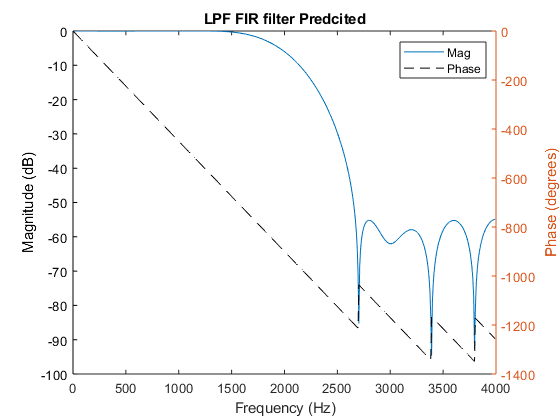

n = 20;                                         %Order
fs = 8000;                                      %Sampling Frequency
fc = 2000;                                      %Cut-off Frequency
b = fir1(n, 2*(fc/fs) , 'low', hamming(n+1));   %numerator coefficients
[h, f] = freqz(b, 1,512, fs);

freq = f;
mag = 20*log10(abs(h(:,:)));
phase = unwrap(angle(h(:,:))) * 57.2958; 

figure(1)
clf
plot(freq,mag)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('LPF FIR filter Predcited')
hold on
yyaxis right
plot(freq,phase(:,:),'k--')
ylabel('Phase (degrees)')
legend('Mag','Phase')
hold off

Gain at 2000 Hz = -6.036dB

Gain at passband edge: -0.03492dB

Stopband edge attenuation: -55.63dB

## FIR Filter Calculations

## 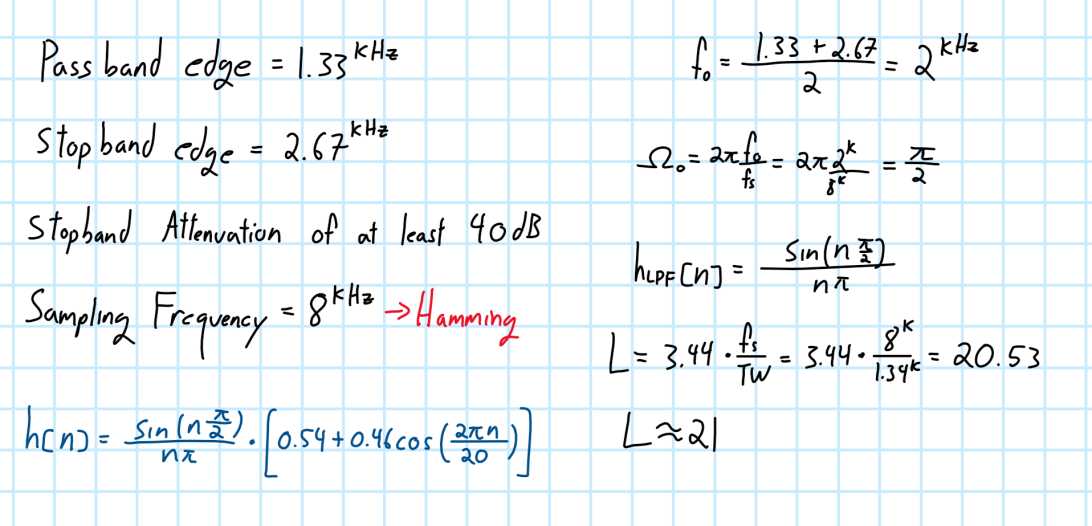

## Export Coefficients

%fir_coeffs(b)

## Measurements

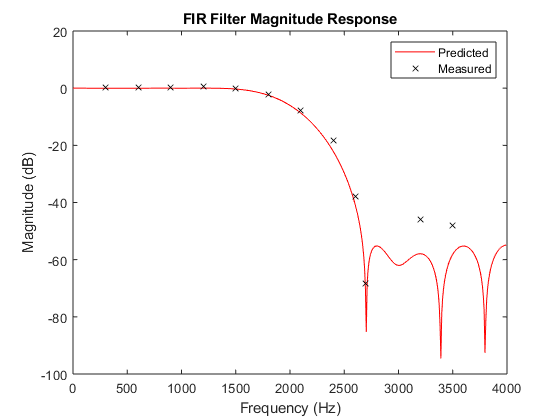

%Measured data; each triplet [f,vout,delay] is 
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [[300, 1.08]
            [600, 1.07]
            [900, 1.07]
            [1200, 1.11]
            [1500, 1.05]
            [1800, 0.830]
            [2100, 0.43]
            [2400, 0.13]
            [2600, 0.0136]
            [2700, 0.0004]
            [3200, 0.0052]
            [3500, 0.0042]
            %cant really read anything in the stop band 
            %guess that means its stopped
           ];

       
           
%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 1.05;


meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);


figure(2)
clf
plot(freq,mag,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('FIR Filter Magnitude Response')
legend('Predicted', 'Measured')

## C code for FM4-176L-S6E2CC-ETH